# **Examen de prácticas**

#### **Fundamentos de Automática - curso 2021/2022**

***Convocatoria ordinaria***

clear;
clc

**Ejercicio 1 (3 puntos)** 

Dado el sistema:


$$\frac{s+2}{s^2+4s+15}$$


(i) (1 punto) Cree la función de transferencia usando tres métodos/comandos diferentes pertenecientes al *Control System Toolbox* de MATLAB.

(ii) (0,5 puntos) Determine la transformada inversa de Laplace de la función de transferencia.

(iii) (1 punto) Evalúe el comportamiento de la respuesta temporal del sistema durante los 5 segundos iniciales.

(iv) (0,5 puntos) Ajuste los ejes de la gráfica obtenida para visualizar correctamente la respuesta. Asigne una leyenda, título y nombre a los ejes de coordenadas.

num=[1 2];
den=[1 4 15];
Tf1=tf(num,den)

Tf1 =
 
      s + 2
  --------------
  s^2 + 4 s + 15
 
Continuous-time transfer function.



s=sym('s')

$$s = s$$

Tf2=((s+2)/(s^2+4*s+15))

$$Tf2 = \frac{s+2}{s^{2}+4\,s+15}$$

Tf3=zpk(roots(num),roots(den),1)

Tf3 =
 
       (s+2)
  ---------------
  (s^2 + 4s + 15)
 
Continuous-time zero/pole/gain model.



a=ilaplace(poly2sym(num,s)/poly2sym(den,s))

$$a = {\mathrm{e}}^{-2\,t}\,\cos\left(\sqrt{11}\,t\right)$$

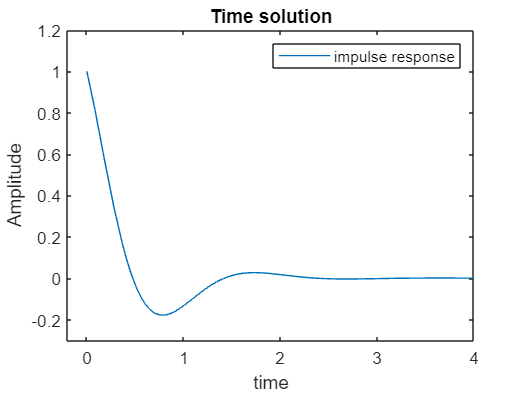

fplot(a,[0 10])
legend('impulse response');
axis([-0.2,4,-0.3,1.2]);
title('Time solution');
xlabel('time');
ylabel('Amplitude');

**Ejercicio 2 (4 puntos) **

Dado el sistema:


$$\frac{s-2}{s^2+6s+25}$$


(i) (0,5 puntos) Dibuje el lugar de las raíces (LDR) del sistema. 

(ii) (1 punto) Encuentre el valor de la ganancia *K*para el punto de confluencia (llegada o salida del eje real) del correspondiente LDR. Se solicita proporcionar una resolución con tres decimales de precisión. Para ello, debe usar un comando de control de flujo tipo *for*. Se recomienda usar herramientas gráficas para definir el rango de búsqueda.

(iii) (1 punto) Determine el valor de la ganancia *K* donde las ramas del LDR cortan con el eje imaginario. Nótese que no se permite el uso de métodos gráficos.

(iv) (1,5 puntos) Encuentre el valor de la ganancia *K* con el que obtener una respuesta ante escalón unitario con una sobreoscilación del 5%. No se permite el uso de métodos gráficos.

% apartado (i)
G=tf([1 -2],[1 6 25])

G =
 
      s - 2
  --------------
  s^2 + 6 s + 25
 
Continuous-time transfer function.



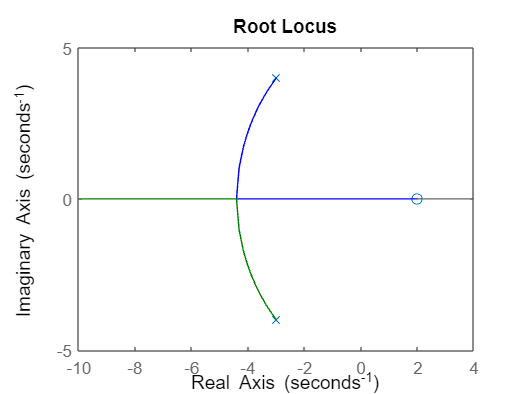

rlocus(G);


% apartado (ii)
K=0;
for(i=2.6:0.001:3)
    [p,K1]=rlocus(G,i);
    if(imag(p)==0 & K==0)
        K=K1;
        solution=p(1);
    end
end
K

K = 2.8070

solution

solution = -4.4729


% apartado (iii)
k2=abs(1/evalfr(G,0))

k2 = 12.5000

K2=0;
for(i=12.3:0.001:12.6)
    [p,K1]=rlocus(G,i);
    if((real(p(1))>0 ||real(p(2))>0) & K2==0)
        K2=K1
        solution=p(1);
    end
end

K2 = 12.5010


% apartado (iv)
MP=100;
K=0;
while MP>0.05
    info=stepinfo(G*K/(1+G*K));
    MP=info.Overshoot;
    K=K+0.001;
end
K

K = 2.3880

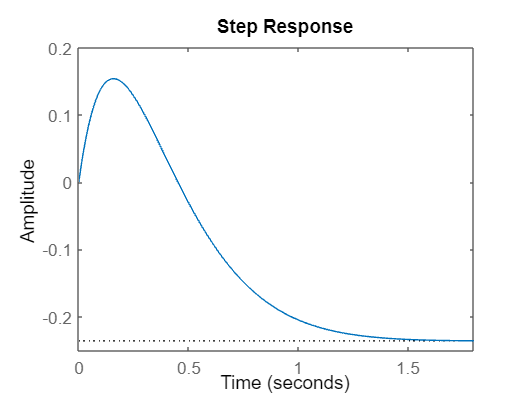

step(G*K/(1+G*K));

stepinfo(G*K/(1+G*K))

ans = struct with fields:
         RiseTime: 0.5727
    TransientTime: 1.2837
     SettlingTime: 1.3738
      SettlingMin: -0.2363
      SettlingMax: -0.2130
        Overshoot: 0.0491
       Undershoot: 65.0772
             Peak: 0.2363
         PeakTime: 2.0753


**Ejercicio 3 (3 puntos) **

Con la ayuda de la herramienta RLTOOL de MATLAB, muestre el diseño de un controlador para la planta 


$$\frac{s+2}{s^2+4s+15}$$


de tal forma que se la respuesta ante escalón unitario presente las siguientes características: tiempo de asentamiento, *t*S< 0,7 segundos (10% tolerancia), sobreoscilación, *M*p = 5% y error en estado estacionario, *e*(∞) = 0. Explique detalladamente el diseño y la selección del tipo de regulador. La solución se proporcionará a través de un *screenshot* o captura de pantalla.